clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b L_ub L_bm theta_C beta Z_arfada ArfadaCaso1 ArfadaCaso2 ArfadaCaso3 CabeceoCaso1 CabeceoCaso2 CabeceoCaso3 BalanceoCaso1 BalanceoCaso2 BalanceoCaso3

Rotula_Placa=0.051

Rotula_Placa = 0.0510

Placa_Biela=0.0145

Placa_Biela = 0.0145


largoB=0.42;
largoM=0.2;
casoL_ub=Rotula_Placa-Placa_Biela

casoL_ub = 0.0365

AlturaPlaca=0.539;
PosXBiela=0.1;
PosYBiela=-0.4145;
PosXEje=0;
PosYEje=-0.4145;
PosZEje=0.2; 


ValoresTiempo(1,:)={'arfada (s)=',double(tMax_a)};
ValoresTiempo(2,:)={'cabeceo (s)=',double(tMax_c)};
ValoresTiempo(3,:)={'balanceo (s)=',double(tMax_b)};

writecell(ValoresTiempo,'docTXT/tiempos_movimientos.txt',"Delimiter",' ')

tiempo=linspace(0,double(tMax_a),80)';
VArfada=double(Fz_arfada(tiempo));
MAA=table(tiempo,VArfada*1000);
writetable(MAA,'docTXT/MAA.txt','delimiter',' ', 'WriteVariableNames', true)

tiempo=linspace(0,double(tMax_c),80)';
VCabeceo=double(Ftheta_c(tiempo));
MCC=table(tiempo,VCabeceo);
writetable(MCC,'docTXT/MCC.txt','delimiter',' ', 'WriteVariableNames', true)

tiempo=linspace(0,double(tMax_b),80)';
Vbalanceo=double(Fbeta(tiempo));
MBB=table(tiempo,Vbalanceo);
writetable(MBB,'docTXT/MBB.txt','delimiter',' ', 'WriteVariableNames', true)



## Arfada

### Caso 1: Arfada simple

tiempo=linspace(0,double(tMax_a),80)';
balanceo=0;
cabeceo=0;
arfada=Fz_arfada;

#### Motor izquierdo

FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaArfadaW=diff(FthetaArfada);
%FthetaArfadaAlpha=diff(FthetaArfadaW);
angulosArfada=double(subs(FthetaArfada,tiempo));
%VelocidadAngularArfada=double(subs(FthetaArfadaW,tiempo));
%AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,tiempo));
ArfadaCaso1iz=table(tiempo,angulosArfada)

ArfadaCaso1iz = 80×2 table
     tiempo      angulosArfada
    _________    _____________

            0       -0.1662   
    0.0040415      -0.16619   
    0.0080829      -0.16613   
     0.012124      -0.16596   
     0.016166      -0.16563   
     0.020207      -0.16509   
     0.024249      -0.16427   
      0.02829      -0.16314   
     0.032332      -0.16164   
     0.036373      -0.15971   
     0.040415      -0.15737   
     0.044456      -0.15461   
     0.048498      -0.15144   
     0.052539      -0.14784   
      0.05658      -0.14384   
     0.060622      -0.13942   


writetable(ArfadaCaso1iz,'docTXT/ArfadaCaso1iz.txt')


#### Motor derecho


FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela -PosYBiela PosXEje -PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaArfadaW=diff(FthetaArfada);
%FthetaArfadaAlpha=diff(FthetaArfadaW);
angulosArfada=double(subs(FthetaArfada,tiempo));
%VelocidadAngularArfada=double(subs(FthetaArfadaW,tiempo));
%AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,tiempo));
ArfadaCaso1de=table(tiempo,angulosArfada)

ArfadaCaso1de = 80×2 table
     tiempo      angulosArfada
    _________    _____________

            0       -0.1662   
    0.0040415      -0.16619   
    0.0080829      -0.16613   
     0.012124      -0.16596   
     0.016166      -0.16563   
     0.020207      -0.16509   
     0.024249      -0.16427   
      0.02829      -0.16314   
     0.032332      -0.16164   
     0.036373      -0.15971   
     0.040415      -0.15737   
     0.044456      -0.15461   
     0.048498      -0.15144   
     0.052539      -0.14784   
      0.05658      -0.14384   
     0.060622      -0.13942   


writetable(ArfadaCaso1de,'docTXT/ArfadaCaso1de.txt')

### Caso 2: Balanceo y cabeceo máximos

tiempo=linspace(0,double(tMax_a),80)';
balanceo=15*pi/180;
cabeceo=18*pi/180;
arfada=Fz_arfada;

#### Motor izquierdo

FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaArfadaW=diff(FthetaArfada);
%FthetaArfadaAlpha=diff(FthetaArfadaW);
angulosArfada=double(subs(FthetaArfada,tiempo));
%VelocidadAngularArfada=double(subs(FthetaArfadaW,tiempo));
%AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,tiempo));
ArfadaCaso2iz=table(tiempo,angulosArfada)

ArfadaCaso2iz = 80×2 table
     tiempo      angulosArfada
    _________    _____________

            0       -1.1621   
    0.0040415       -1.1621   
    0.0080829        -1.162   
     0.012124       -1.1616   
     0.016166       -1.1609   
     0.020207       -1.1598   
     0.024249       -1.1581   
      0.02829       -1.1558   
     0.032332       -1.1527   
     0.036373       -1.1487   
     0.040415        -1.144   
     0.044456       -1.1383   
     0.048498       -1.1319   
     0.052539       -1.1246   
      0.05658       -1.1166   
     0.060622       -1.1078   


writetable(ArfadaCaso2iz,'docTXT/ArfadaCaso2iz.txt')


#### Motor derecho

FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela -PosYBiela PosXEje -PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaArfadaW=diff(FthetaArfada);
%FthetaArfadaAlpha=diff(FthetaArfadaW);
angulosArfada=double(subs(FthetaArfada,tiempo));
%VelocidadAngularArfada=double(subs(FthetaArfadaW,tiempo));
%AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,tiempo));
ArfadaCaso2de=table(tiempo,angulosArfada)

ArfadaCaso2de = 80×2 table
     tiempo      angulosArfada
    _________    _____________

            0       0.20089   
    0.0040415        0.2009   
    0.0080829       0.20095   
     0.012124       0.20111   
     0.016166       0.20142   
     0.020207       0.20192   
     0.024249       0.20267   
      0.02829       0.20372   
     0.032332       0.20512   
     0.036373        0.2069   
     0.040415       0.20907   
     0.044456       0.21163   
     0.048498       0.21459   
     0.052539       0.21794   
      0.05658       0.22167   
     0.060622       0.22581   


writetable(ArfadaCaso2de,'docTXT/ArfadaCaso2de.txt')

### Caso 3: Balanceo y cabeceo mínimos

tiempo=linspace(0,double(tMax_a),80)';
balanceo=-15*pi/180;
cabeceo=-18*pi/180;
arfada=Fz_arfada;

#### Motor izquierdo

%theta1
FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaArfadaW=diff(FthetaArfada);
%FthetaArfadaAlpha=diff(FthetaArfadaW);
%plot(t,Ftheta())
angulosArfada=double(subs(FthetaArfada,tiempo));
%VelocidadAngularArfada=double(subs(FthetaArfadaW,tiempo));
%AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,tiempo));
ArfadaCaso3iz=table(tiempo,angulosArfada)

ArfadaCaso3iz = 80×2 table
     tiempo      angulosArfada
    _________    _____________

            0       0.52596   
    0.0040415       0.52597   
    0.0080829       0.52603   
     0.012124        0.5262   
     0.016166       0.52652   
     0.020207       0.52705   
     0.024249       0.52784   
      0.02829       0.52894   
     0.032332       0.53041   
     0.036373       0.53228   
     0.040415       0.53457   
     0.044456       0.53728   
     0.048498        0.5404   
     0.052539       0.54395   
      0.05658       0.54791   
     0.060622        0.5523   


writetable(ArfadaCaso3iz,'docTXT/ArfadaCaso3iz.txt')

#### Motor derecho

FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela -PosYBiela PosXEje -PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaArfadaW=diff(FthetaArfada);
%FthetaArfadaAlpha=diff(FthetaArfadaW);
angulosArfada=double(subs(FthetaArfada,tiempo));
%VelocidadAngularArfada=double(subs(FthetaArfadaW,tiempo));
%AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,tiempo));
ArfadaCaso3de=table(tiempo,angulosArfada)

ArfadaCaso3de = 80×2 table
     tiempo      angulosArfada
    _________    _____________

            0      -0.62855   
    0.0040415      -0.62854   
    0.0080829      -0.62845   
     0.012124      -0.62822   
     0.016166      -0.62777   
     0.020207      -0.62704   
     0.024249      -0.62593   
      0.02829       -0.6244   
     0.032332      -0.62236   
     0.036373      -0.61977   
     0.040415      -0.61661   
     0.044456      -0.61289   
     0.048498      -0.60862   
     0.052539       -0.6038   
      0.05658      -0.59843   
     0.060622      -0.59254   


writetable(ArfadaCaso3de,'docTXT/ArfadaCaso3de.txt')

## Cabeceo

### Caso 1: Balanceo y arfada nula

tiempo=linspace(0,double(tMax_c),80)';
balanceo=0; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0; %valor de arfada

#### Motor izquierdo

FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaCabeceoW=diff(FthetaCabeceo);
%FthetaCabeceoAlpha=diff(FthetaCabeceoW);
angulosCabeceo=double(subs(FthetaCabeceo,tiempo));
%VelocidadAngularCabeceo=double(subs(FthetaCabeceoW,tiempo));
%AceleracionAngularCabeceo=double(subs(FthetaCabeceoAlpha,tiempo));
CabeceoCaso1iz=table(tiempo,angulosCabeceo)

CabeceoCaso1iz = 80×2 table
     tiempo     angulosCabeceo
    ________    ______________

           0        0.005006  
    0.015865       0.0050006  
    0.031729       0.0049625  
    0.047594        0.004859  
    0.063459       0.0046574  
    0.079324       0.0043251  
    0.095188       0.0038291  
     0.11105       0.0031365  
     0.12692       0.0022143  
     0.14278       0.0010364  
     0.15865     -0.00040207  
     0.17451      -0.0021019  
     0.19038      -0.0040643  
     0.20624      -0.0062904  
     0.22211      -0.0087817  
     0.23797        -0.01154  


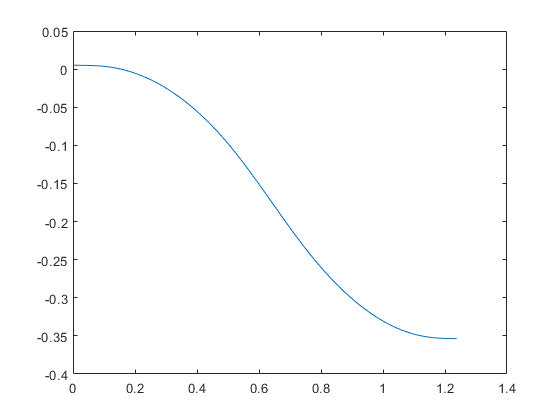

writetable(CabeceoCaso1iz,'docTXT/CabeceoCaso1iz.txt')

plot(CabeceoCaso1iz.tiempo,CabeceoCaso1iz.angulosCabeceo)

#### Motor derecho

FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela -PosYBiela PosXEje -PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaCabeceoW=diff(FthetaCabeceo);
%FthetaCabeceoAlpha=diff(FthetaCabeceoW);
angulosCabeceo=double(subs(FthetaCabeceo,tiempo));
%VelocidadAngularCabeceo=double(subs(FthetaCabeceoW,tiempo));
%AceleracionAngularCabeceo=double(subs(FthetaCabeceoAlpha,tiempo));
CabeceoCaso1de=table(tiempo,angulosCabeceo)

CabeceoCaso1de = 80×2 table
     tiempo     angulosCabeceo
    ________    ______________

           0        0.005006  
    0.015865       0.0050006  
    0.031729       0.0049625  
    0.047594        0.004859  
    0.063459       0.0046574  
    0.079324       0.0043251  
    0.095188       0.0038291  
     0.11105       0.0031365  
     0.12692       0.0022143  
     0.14278       0.0010364  
     0.15865     -0.00040207  
     0.17451      -0.0021019  
     0.19038      -0.0040643  
     0.20624      -0.0062904  
     0.22211      -0.0087817  
     0.23797        -0.01154  


writetable(CabeceoCaso1de,'docTXT/CabeceoCaso1de.txt')

### Caso 2: Balanceo máximo, arfada nula

tiempo=linspace(0,double(tMax_c),80)';
balanceo=15*pi/180; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0; %valor de arfada

#### Motor izquierdo

FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaCabeceoW=diff(FthetaCabeceo);
%FthetaCabeceoAlpha=diff(FthetaCabeceoW);
angulosCabeceo=double(subs(FthetaCabeceo,tiempo));
%VelocidadAngularCabeceo=double(subs(FthetaCabeceoW,tiempo));
%AceleracionAngularCabeceo=double(subs(FthetaCabeceoAlpha,tiempo));
CabeceoCaso2iz=table(tiempo,angulosCabeceo)

CabeceoCaso2iz = 80×2 table
     tiempo     angulosCabeceo
    ________    ______________

           0       -0.62855   
    0.015865       -0.62856   
    0.031729        -0.6286   
    0.047594       -0.62874   
    0.063459         -0.629   
    0.079324       -0.62944   
    0.095188       -0.63009   
     0.11105       -0.63099   
     0.12692        -0.6322   
     0.14278       -0.63374   
     0.15865       -0.63562   
     0.17451       -0.63785   
     0.19038       -0.64042   
     0.20624       -0.64334   
     0.22211       -0.64661   
     0.23797       -0.65024   


writetable(CabeceoCaso2iz,'docTXT/CabeceoCaso2iz.txt')

#### Motor derecho

FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela -PosYBiela PosXEje -PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaCabeceoW=diff(FthetaCabeceo);
%FthetaCabeceoAlpha=diff(FthetaCabeceoW);
angulosCabeceo=double(subs(FthetaCabeceo,tiempo));
%VelocidadAngularCabeceo=double(subs(FthetaCabeceoW,tiempo));
%AceleracionAngularCabeceo=double(subs(FthetaCabeceoAlpha,tiempo));
CabeceoCaso2de=table(tiempo,angulosCabeceo)

CabeceoCaso2de = 80×2 table
     tiempo     angulosCabeceo
    ________    ______________

           0       0.52596    
    0.015865       0.52596    
    0.031729       0.52592    
    0.047594       0.52582    
    0.063459       0.52562    
    0.079324        0.5253    
    0.095188       0.52482    
     0.11105       0.52415    
     0.12692       0.52326    
     0.14278       0.52211    
     0.15865       0.52072    
     0.17451       0.51908    
     0.19038       0.51718    
     0.20624       0.51502    
     0.22211       0.51262    
     0.23797       0.50995    


writetable(CabeceoCaso2de,'docTXT/CabeceoCaso2de.txt')

### Caso 3: Balanceo minimo, arfada máxima 

tiempo=linspace(0,double(tMax_c),80)';
balanceo=-15*pi/180; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0.1; %valor de arfada

#### Motor izquierdo

FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaCabeceoW=diff(FthetaCabeceo);
%FthetaCabeceoAlpha=diff(FthetaCabeceoW);
angulosCabeceo=double(subs(FthetaCabeceo,tiempo));
%VelocidadAngularCabeceo=double(subs(FthetaCabeceoW,tiempo));
%AceleracionAngularCabeceo=double(subs(FthetaCabeceoAlpha,tiempo));
CabeceoCaso3iz=table(tiempo,angulosCabeceo)

CabeceoCaso3iz = 80×2 table
     tiempo     angulosCabeceo
    ________    ______________

           0        1.2811    
    0.015865        1.2811    
    0.031729        1.2809    
    0.047594        1.2806    
    0.063459        1.2799    
    0.079324        1.2788    
    0.095188        1.2771    
     0.11105        1.2748    
     0.12692        1.2718    
     0.14278         1.268    
     0.15865        1.2635    
     0.17451        1.2583    
     0.19038        1.2524    
     0.20624        1.2459    
     0.22211        1.2388    
     0.23797        1.2312    


writetable(CabeceoCaso3iz,'docTXT/CabeceoCaso3iz.txt')

#### Motor derecho

FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela -PosYBiela PosXEje -PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaCabeceoW=diff(FthetaCabeceo);
%FthetaCabeceoAlpha=diff(FthetaCabeceoW);
angulosCabeceo=double(subs(FthetaCabeceo,tiempo));
%VelocidadAngularCabeceo=double(subs(FthetaCabeceoW,tiempo));
%AceleracionAngularCabeceo=double(subs(FthetaCabeceoAlpha,tiempo));
CabeceoCaso3de=table(tiempo,angulosCabeceo)

CabeceoCaso3de = 80×2 table
     tiempo     angulosCabeceo
    ________    ______________

           0      -0.042798   
    0.015865      -0.042803   
    0.031729      -0.042841   
    0.047594      -0.042943   
    0.063459      -0.043142   
    0.079324       -0.04347   
    0.095188       -0.04396   
     0.11105      -0.044644   
     0.12692      -0.045555   
     0.14278      -0.046719   
     0.15865      -0.048139   
     0.17451      -0.049818   
     0.19038      -0.051756   
     0.20624      -0.053954   
     0.22211      -0.056414   
     0.23797      -0.059137   


writetable(CabeceoCaso3de,'docTXT/CabeceoCaso3de.txt')

## Balanceo

### Caso 1: Cabeceo y arfada nula 

tiempo=linspace(0,double(tMax_b),80)';
balanceo=Fbeta; %valor de balanceo en radianes
cabeceo=0; %valor cabeceo en radianes
arfada=0; %valor de arfada

#### Motor izquierdo

FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaBalanceoW=diff(FthetaBalanceo);
%FthetaBalanceoAlpha=diff(FthetaBalanceoW);
angulosBalanceo=double(subs(FthetaBalanceo,tiempo));
%VelocidadAngularBalanceo=double(subs(FthetaBalanceoW,tiempo));
%AceleracionAngularBalanceo=double(subs(FthetaBalanceoAlpha,tiempo));
BalanceoCaso1iz=table(tiempo,angulosBalanceo)

BalanceoCaso1iz = 80×2 table
     tiempo     angulosBalanceo
    ________    _______________

           0        0.36448    
    0.014482        0.36447    
    0.028965        0.36434    
    0.043447        0.36401    
     0.05793        0.36337    
    0.072412         0.3623    
    0.086895        0.36071    
     0.10138        0.35849    
     0.11586        0.35554    
     0.13034        0.35177    
     0.14482        0.34718    
     0.15931        0.34176    
     0.17379        0.33552    
     0.18827        0.32845    
     0.20275        0.32057    
     0.21724        0.31186    


writetable(BalanceoCaso1iz,'docTXT/BalanceoCaso1iz.txt')

#### Motor derecho

FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela -PosYBiela PosXEje -PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaBalanceoW=diff(FthetaBalanceo);
%FthetaBalanceoAlpha=diff(FthetaBalanceoW);
angulosBalanceo=double(subs(FthetaBalanceo,tiempo));
%VelocidadAngularBalanceo=double(subs(FthetaBalanceoW,tiempo));
%AceleracionAngularBalanceo=double(subs(FthetaBalanceoAlpha,tiempo));
BalanceoCaso1de=table(tiempo,angulosBalanceo)

BalanceoCaso1de = 80×2 table
     tiempo     angulosBalanceo
    ________    _______________

           0        -0.8627    
    0.014482       -0.86266    
    0.028965       -0.86245    
    0.043447       -0.86188    
     0.05793       -0.86075    
    0.072412        -0.8589    
    0.086895       -0.85615    
     0.10138       -0.85232    
     0.11586       -0.84724    
     0.13034       -0.84079    
     0.14482       -0.83297    
     0.15931        -0.8238    
     0.17379       -0.81331    
     0.18827       -0.80154    
     0.20275       -0.78852    
     0.21724       -0.77429    


writetable(BalanceoCaso1de,'docTXT/BalanceoCaso1de.txt')

### Caso 2: Cabeceo máximo, arfada nula 

tiempo=linspace(0,double(tMax_b),80)';
balanceo=Fbeta; %valor de balanceo en radianes
cabeceo=18*pi/180; %valor cabeceo en radianes
arfada=0; %valor de arfada




#### Motor izquierdo

FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaBalanceoW=diff(FthetaBalanceo);
%FthetaBalanceoAlpha=diff(FthetaBalanceoW);
angulosBalanceo=double(subs(FthetaBalanceo,tiempo));
%VelocidadAngularBalanceo=double(subs(FthetaBalanceoW,tiempo));
%AceleracionAngularBalanceo=double(subs(FthetaBalanceoAlpha,tiempo));
BalanceoCaso2iz=table(tiempo,angulosBalanceo)

BalanceoCaso2iz = 80×2 table
     tiempo     angulosBalanceo
    ________    _______________

           0        0.20089    
    0.014482        0.20087    
    0.028965        0.20075    
    0.043447        0.20042    
     0.05793        0.19977    
    0.072412        0.19871    
    0.086895        0.19712    
     0.10138         0.1949    
     0.11586        0.19195    
     0.13034        0.18819    
     0.14482        0.18359    
     0.15931        0.17817    
     0.17379        0.17191    
     0.18827        0.16482    
     0.20275        0.15689    
     0.21724        0.14812    


writetable(BalanceoCaso2iz,'docTXT/BalanceoCaso2iz.txt')

#### Motor derecho

FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela -PosYBiela PosXEje -PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaBalanceoW=diff(FthetaBalanceo);
%FthetaBalanceoAlpha=diff(FthetaBalanceoW);
angulosBalanceo=double(subs(FthetaBalanceo,tiempo));
%VelocidadAngularBalanceo=double(subs(FthetaBalanceoW,tiempo));
%AceleracionAngularBalanceo=double(subs(FthetaBalanceoAlpha,tiempo));
BalanceoCaso2de=table(tiempo,angulosBalanceo)

BalanceoCaso2de = 80×2 table
     tiempo     angulosBalanceo
    ________    _______________

           0        -1.1621    
    0.014482        -1.1621    
    0.028965        -1.1618    
    0.043447        -1.1611    
     0.05793        -1.1597    
    0.072412        -1.1573    
    0.086895        -1.1538    
     0.10138         -1.149    
     0.11586        -1.1425    
     0.13034        -1.1344    
     0.14482        -1.1246    
     0.15931        -1.1131    
     0.17379           -1.1    
     0.18827        -1.0854    
     0.20275        -1.0692    
     0.21724        -1.0517    


writetable(BalanceoCaso2de,'docTXT/BalanceoCaso2de.txt')

### Caso 3: Cabeceo minimo, arfada máxima

tiempo=linspace(0,double(tMax_b),80)';
balanceo=Fbeta; %valor de balanceo en radianes
cabeceo=-18*pi/180;
arfada=0.1; %valor de arfada

#### Motor izquierdo

FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaBalanceoW=diff(FthetaBalanceo);
%FthetaBalanceoAlpha=diff(FthetaBalanceoW);
angulosBalanceo=double(subs(FthetaBalanceo,tiempo));
%VelocidadAngularBalanceo=double(subs(FthetaBalanceoW,tiempo));
%AceleracionAngularBalanceo=double(subs(FthetaBalanceoAlpha,tiempo));
BalanceoCaso3iz=table(tiempo,angulosBalanceo)

BalanceoCaso3iz = 80×2 table
     tiempo     angulosBalanceo
    ________    _______________

           0        1.2811     
    0.014482         1.281     
    0.028965        1.2805     
    0.043447         1.279     
     0.05793        1.2762     
    0.072412        1.2716     
    0.086895         1.265     
     0.10138        1.2562     
     0.11586        1.2451     
     0.13034        1.2318     
     0.14482        1.2166     
     0.15931        1.1999     
     0.17379        1.1819     
     0.18827        1.1629     
     0.20275         1.143     
     0.21724        1.1223     


writetable(BalanceoCaso3iz,'docTXT/BalanceoCaso3iz.txt')

#### Motor derecho

FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b L_ub theta_C beta Z_arfada],[AlturaPlaca PosXBiela -PosYBiela PosXEje -PosYEje PosZEje largoM largoB casoL_ub cabeceo balanceo arfada]);
%FthetaBalanceoW=diff(FthetaBalanceo);
%FthetaBalanceoAlpha=diff(FthetaBalanceoW);
angulosBalanceo=double(subs(FthetaBalanceo,tiempo));
%VelocidadAngularBalanceo=double(subs(FthetaBalanceoW,tiempo));
%AceleracionAngularBalanceo=double(subs(FthetaBalanceoAlpha,tiempo));
BalanceoCaso3de=table(tiempo,angulosBalanceo)

BalanceoCaso3de = 80×2 table
     tiempo     angulosBalanceo
    ________    _______________

           0       -0.042798   
    0.014482       -0.042779   
    0.028965       -0.042648   
    0.043447       -0.042292   
     0.05793       -0.041599   
    0.072412       -0.040457   
    0.086895       -0.038754   
     0.10138       -0.036379   
     0.11586       -0.033221   
     0.13034       -0.029195   
     0.14482        -0.02429   
     0.15931       -0.018509   
     0.17379       -0.011856   
     0.18827      -0.0043361   
     0.20275       0.0040467   
     0.21724        0.013287   


writetable(BalanceoCaso3de,'docTXT/BalanceoCaso3de.txt')